# Object Tracking using Image Features

This example shows how to detect an object based on feature extraction and matching, and then how to track the object using the KLT feature-tracking algorithm. 

We highly recommend you to complete the [Image Processing Onramp](http://bit.ly/2OOtJiB).

Copyright 2021 The MathWorks, Inc.

close all; clear; clc;
rng(250);

## Extract Image Features of an Object

#### Load Reference Image  

Read an reference image showing a predefined object. We resize the image to reduce the number of computations and then display it

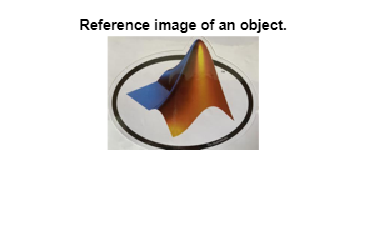

refImg = imread("MWLogo.jpg");
refImg = imresize(refImg,0.3); 

figure
imshow(refImg);
title('Reference image of an object.')

Change the color space of the reference image to intensity (grayscale)

refImgGray = rgb2gray(refImg);

#### Detect and Extract Features in Reference Image 

Please select wether to use a scale-dependent feature detection method or a scale-independent one

methodsType = "scale-independent";

Detect features in the reference image with a method depending on your selection 

if methodsType == "scale-dependent"
    refPts = detectHarrisFeatures(refImgGray);
else % scale-independent methods
    refPts = detectSURFFeatures(refImgGray);
end



Extract features with '`Auto`' (default) selected method.

[refFeatures,refPoints] = extractFeatures(refImgGray,refPts);

Display the 10 strongest feature points

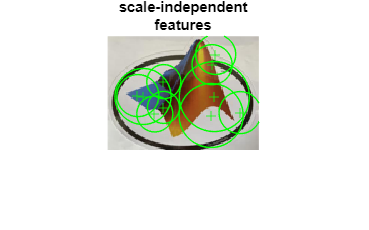

figure;
imshow(refImg);
hold on;
plot(refPoints.selectStrongest(10));
title(['Extracted' methodsType 'features'])

Calculate the box polygon of the reference image for futher marking the boundary of the object in a target video 

refBoxPolygon = getBoxPolygonOfImg(refImg);

## Dectect Object in a Video Based on Features

#### Load Target Video

Read an target video with an selected name using Video Reader object.

targetVid = "moveCamera.mp4";
vidReader = VideoReader(targetVid);

#### Detect Object Based on Feature Matching

Create an video player object to display the target video

vidPlayer = vision.VideoPlayer('Position', [40,40,854,480]);

Initialize a status variable to indicate if there is enought inliers (correctly matched points) have been found:

- 0: Enough inliers have been found

- 1: Matched feature pair do not contain enough points.

- 2: Not enough inliers have been found 

status = 2;

Loop the video frames and perform feature detection, extraction and mathching until the object showing in the reference image is detected in the video. Mark the object and then display using a [Video Player](https://www.mathworks.com/help/vision/ref/vision.videoplayer-system-object.html). 

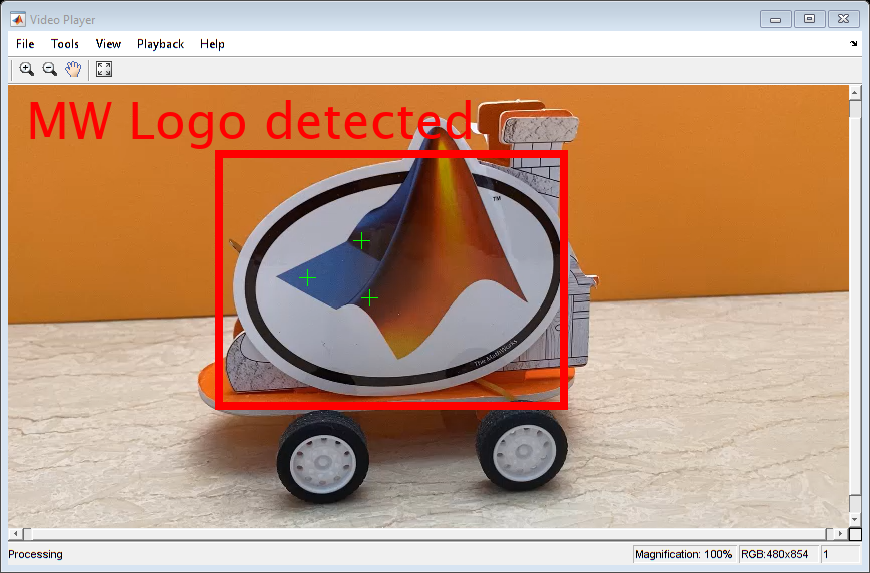

% Read video frames until the last one or if there are enough inliers have
% been found
while(hasFrame(vidReader) && status)

    % Read the next frame
    sceneImg = readFrame(vidReader);
    sceneImgGray = im2gray(sceneImg);

    % Detect feature points using the same method as in the reference image
    if methodsType == "scale-dependent"
        scenePts = detectHarrisFeatures(sceneImgGray);
    else % scale-independent methods
        scenePts = detectSURFFeatures(sceneImgGray);
    end

    % Extract feature descriptors
    [sceneFeatures, scenePoints] = extractFeatures(sceneImgGray, scenePts);

    % Match Features
    idxPairs = matchFeatures(refFeatures,sceneFeatures);

    % Get putatively matched feature points
    matchedRefPts = refPoints(idxPairs(:, 1), :);
    matchedScenePts = scenePoints(idxPairs(:, 2), :);

    % Estimate Geometric Transformation and Eliminate Outliers
    [refTform, inlierIdx, status] = ...
        estimateGeometricTransform2D(matchedRefPts, matchedScenePts, 'affine');

    % Initilize output frame
    outImg =  sceneImg;

    % If there are enough inliers, insert text to the frame to show the detection result
    if status == 0
        % Indicate if the object have been detected
        outImg = insertText(outImg, [10 10], 'MW Logo detected', 'FontSize', 50,'TextColor','red', 'BoxOpacity',0);

        % Mark the inliers
        inliers = matchedScenePts(inlierIdx, :);
        outImg = insertMarker(outImg,inliers,'+','size',8);

        % Mark the boundary of the object detected
        objBoxPolygon = transformPointsForward(refTform, refBoxPolygon);
        objRegion = boxPolygon2recRegion(objBoxPolygon);
        outImg = insertShape(outImg,'Rectangle',objRegion,'Color','red','LineWidth', 8);
    end

    % Display the frame using the video player
    step(vidPlayer,outImg);
end

Pause 2 secs so the object detected information can be seen clearly.

pause(2);

## Tracking Object based on Features

#### Create and Initialize a Point Tracker

if ~status % if there are enough inliers
    tracker = vision.PointTracker('MaxBidirectionalError',2);
    initialize(tracker,inliers.Location,sceneImg);
end

Loop the rest of the video frames and perform feature detection, extraction and mathching until the object showing in the reference image is detected in the video. Mark the object and then display using a [Video Player](https://www.mathworks.com/help/vision/ref/vision.videoplayer-system-object.html). 

% Track the inliers in the rest frames
while(hasFrame(vidReader))

    % Read the next frame
    sceneImg = readFrame(vidReader);

    % Find newly tracked points
    [trackedPts,isValid] = step(tracker,sceneImg);

    % Use only the locations that have been reliably tracked
    newValidLocation = trackedPts(isValid,:);
    oldValidLocation = inliers.Location(isValid, :);

    % Initilize output frame and object polygon
    outImg =  sceneImg;

    % Indicate if we are tracking the object
    outImg = insertText(outImg, [10 10], 'MW Logo tracking', 'FontSize', 50,'TextColor','red', 'BoxOpacity',0);

    % Mark the tracked points
    outImg = insertMarker(outImg,newValidLocation,'+','size',8);

    % Update trackingTform when having at least 2 tracked points between frames
    if (nnz(isValid) >= 2)
        % Reset Point Tracker for tracking the object in the next frame
        setPoints(tracker,newValidLocation);

        % Estimate geometric transformation between two frames
        [trackingTform, newInlierIdx, status] = ...
            estimateGeometricTransform2D(oldValidLocation, newValidLocation, 'Similarity');

        % Accumulate geometric transformations from reference to current
        % frame
        trackingTform.T = refTform.T * trackingTform.T;

        % Update the object polygon
        objBoxPolygon = transformPointsForward(trackingTform, refBoxPolygon);

        % Mark the boundary of the object tracked
        objRegion = boxPolygon2recRegion(objBoxPolygon);
        outImg = insertShape(outImg,'Rectangle',objRegion,'Color','red','LineWidth', 8);
    end

    % Display the frame using the video player
    step(vidPlayer,outImg);

    % Pause 0.05 secs so the video does not play so fast
    pause(0.05)
end

% Release the video player
release(vidPlayer)



## Helper Functions

Get polygon indicate the boundary of the image

function boxPolygon = getBoxPolygonOfImg(image)
imgRegion =  ones(4,1);
imgRegion(3) = size(image,2);
imgRegion(4) = size(image,1);
boxPolygon = [imgRegion(1), imgRegion(2);...                   % top-left
    imgRegion(1) + imgRegion(3), imgRegion(2);...              % top-right
    imgRegion(1) + imgRegion(3), imgRegion(2)+imgRegion(4);... % bottom-right
    imgRegion(1), imgRegion(2) + imgRegion(4);...              % bottom-left
    imgRegion(1), imgRegion(2)];                               % top-left again to close the polygon
end

Transfer a polygon to a image region: [x_0, y_0, x_size,y_size]

function recRegion = boxPolygon2recRegion(boxPolygon)
recRegion = [boxPolygon(1,1),boxPolygon(1,2),(boxPolygon(2,1)-boxPolygon(1,1)),(boxPolygon(4,2)-boxPolygon(1,2))];
end

## Future Tasks

- Tune parameter *MaxBidirectionalError *of the tracker to see the difference in the results. Notice any difference?

- Try to use another display methods [*imshow*](https://www.mathworks.com/help/images/ref/imshow.html) and investigate the difference in time with [*Video Playe*](https://www.mathworks.com/help/vision/ref/vision.videoplayer-system-object.html)*r* using [*tic*](https://www.mathworks.com/help/matlab/ref/tic.html) and [*toc*](https://www.mathworks.com/help/matlab/ref/toc.html).  